judp('send', 8080, '192.168.178.100', int8(21))

MSSG = judp('RECEIVE', 8080, 600)

MSSG = 600×1 int8 column vector
   114
   116
   115
   115
   116
   114
   118
   112
   113
   120


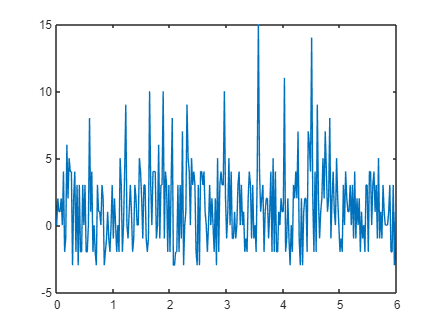


X = int16(MSSG);
for i= 1:600
    if (X(i) < 0)
        X(i) = X(i) + 255;
    else
        X(i) = X(i);
    end
end

speed = 20;
ts = 0.02;
len = 300;
X0 = X(1:len);
X1 = X(len + 1:2*len);
y = X1 * 255 + X0;
t = 0:ts:ts*(len-1);
ts_angle = 360/60*speed*ts;
x = 0:ts_angle:ts_angle*(len-1);
y = y - y(1);

plot(t, y)